% Limpiar el espacio de trabajo, la ventana de comandos y cerrar figuras
clear;    
clc;     
close all;

% Definir los parámetros simbólicos
syms eta alpha1 beta1 gamma1 mu1 alpha2 beta2 gamma2 mu2 alpha3 beta3 tau x1 x2 x3 C
assume(eta >=0)


## MATRIZ JACOBIANA

% Definir las ecuaciones
f1 = (alpha1 * x1 * (C - x1 - x2 - x3)) / (1 + gamma1 * x3) - x1 * (beta1 + mu1 * x3);
f2 = (alpha2 * x2 * (C - x1 - x2 - x3) * (1 + tau * x1)) / (1 + x3 * gamma2) - x2 * (beta2 + mu2 * x3);
f3 = alpha3 * x3 * (C - x1 - x2 - x3) - (beta3 + eta) * x3;

% Definir el sistema de ecuaciones
F = [f1; f2; f3];

% Definir las variables
vars = [x1, x2, x3];


%% Calcular la matriz Jacobiana

J = jacobian(F, vars)

$$J = \begin{array}{l} \left(\begin{array}{ccc} -\beta_{1}-\mu_{1}\,x_{3}-\frac{\alpha_{1}\,\left(x_{1}-C+x_{2}+x_{3}\right)}{\gamma_{1}\,x_{3}+1}-\sigma_{2} & -\sigma_{2} & \frac{\alpha_{1}\,\gamma_{1}\,x_{1}\,\left(x_{1}-C+x_{2}+x_{3}\right)}{{\left(\gamma_{1}\,x_{3}+1\right)}^{2}}-\sigma_{2}-\mu_{1}\,x_{1}\\ -\sigma_{1}-\frac{\alpha_{2}\,\tau \,x_{2}\,\left(x_{1}-C+x_{2}+x_{3}\right)}{\gamma_{2}\,x_{3}+1} & -\beta_{2}-\mu_{2}\,x_{3}-\frac{\alpha_{2}\,\left(\tau \,x_{1}+1\right)\,\left(x_{1}-C+x_{2}+x_{3}\right)}{\gamma_{2}\,x_{3}+1}-\sigma_{1} & \frac{\alpha_{2}\,\gamma_{2}\,x_{2}\,\left(\tau \,x_{1}+1\right)\,\left(x_{1}-C+x_{2}+x_{3}\right)}{{\left(\gamma_{2}\,x_{3}+1\right)}^{2}}-\sigma_{1}-\mu_{2}\,x_{2}\\ -\alpha_{3}\,x_{3} & -\alpha_{3}\,x_{3} & -\beta_{3}-\eta -\alpha_{3}\,\left(x_{1}-C+x_{2}+x_{3}\right)-\alpha_{3}\,x_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\alpha_{2}\,x_{2}\,\left(\tau \,x_{1}+1\right)}{\gamma_{2}\,x_{3}+1}\\ \sigma_{2}=\frac{\alpha_{1}\,x_{1}}{\gamma_{1}\,x_{3}+1} \end{array}$$


% Definir los valores de los parámetros
alpha1_val = 0.00137;
beta1_val = 0.07;
gamma1_val = 0.01;
mu1_val = 0.01;
alpha2_val = 0.0011;
beta2_val = 0.29;
gamma2_val = 0.01;
mu2_val = 0.01;
alpha3_val = 0.001;
beta3_val = 0.1;
tau_val = 0.0995;
C_val = 146.9;

% Modificar
%eta = 0.05;

sigma1 = 1/(2*gamma2_val*mu2_val)*( -(beta2_val*gamma2_val + mu2_val) + sqrt( (beta2_val*gamma2_val-mu2_val)^2 + (4*gamma2_val*mu2_val*alpha2_val*(beta3_val+eta))/alpha3_val ) );
sigma2 = 1/(2*gamma1_val*mu1_val)*( -(beta1_val*gamma1_val + mu1_val) + sqrt( (beta1_val*gamma1_val-mu1_val)^2 + (4*gamma1_val*mu1_val*alpha1_val*(beta3_val+eta))/alpha3_val ) );

% Definir el valor de punto
punto = "p7";

if punto == "p0"
    % Si punto es igual a p1, calcular las fórmulas
    x1_formula = 0;
    x2_formula = 0;
    x3_formula = 0;
elseif punto == "p1"
    % Si punto es igual a p2, calcular las fórmulas
    x1_formula = 0;
    x2_formula = 0;
    x3_formula = C_val - (beta3_val+eta)/alpha3_val;
elseif punto == "p2"
    % Si punto es igual a p3, calcular las fórmulas
    x1_formula = 0;
    x2_formula = C_val - beta2_val/alpha2_val;
    x3_formula = 0;
elseif punto == "p3"
    % Si punto es igual a p4, calcular las fórmulas
    x1_formula = 0;
    x2_formula = C_val - sigma1 - (beta3_val+eta)/alpha3_val;
    x3_formula = sigma1;
elseif punto == "p4"
    % Si punto es igual a p5, calcular las fórmulas
    x1_formula = C_val - beta1_val/alpha1_val;
    x2_formula = 0;
    x3_formula = 0;
elseif punto == "p5"
    % Si punto es igual a p6, calcular las fórmulas
    x1_formula = C_val - sigma2 - (beta3_val + eta) / alpha3_val;
    x2_formula = 0;
    x3_formula = sigma2;
elseif punto == "p6"
    % Si punto es igual a p7, calcular las fórmulas
    x1_formula = (alpha1_val*beta2_val-alpha2_val*beta1_val)/(alpha2_val*beta1_val*tau_val);
    x2_formula = C_val - x1_formula - beta1_val/alpha1_val;
    x3_formula = 0;
else
    % Si punto es igual a p8, calcular las fórmulas
    x1_formula = (alpha3_val*((beta2_val+mu2_val*sigma2)*(gamma2_val*sigma2+1) - (alpha2_val*(beta3_val+eta)/alpha3_val)))/(alpha2_val*tau_val*(beta3_val+eta));
    x2_formula = C_val - x1_formula - sigma2 - (beta3_val+eta)/alpha3_val;
    x3_formula = sigma2;
end


% Verificar
f1 = (alpha1_val * x1_formula * (C_val - x1_formula - x2_formula - x3_formula)) / (1 + gamma1_val * x3_formula) - x1_formula * (beta1_val + mu1_val * x3_formula);
f2 = (alpha2_val * x2_formula * (C_val - x1_formula - x2_formula - x3_formula) * (1 + tau_val * x1_formula)) / (1 + x3_formula * gamma2_val) - x2_formula * (beta2_val + mu2_val * x3_formula);
f3 = alpha3_val * x3_formula * (C_val - x1_formula - x2_formula - x3_formula) - (beta3_val + eta) * x3_formula;

% Crear la lista de parámetros sin incluir eta
param_vals = [alpha1, beta1, gamma1, mu1, alpha2, beta2, gamma2, mu2, alpha3, beta3, tau, C, x1, x2, x3];
param_subs = [alpha1_val, beta1_val, gamma1_val, mu1_val, alpha2_val, beta2_val, gamma2_val, mu2_val, alpha3_val, beta3_val, tau_val, C_val, x1_formula, x2_formula, x3_formula];

% Evaluar la matriz Jacobiana con los valores de los parámetros excepto eta
J_simb = subs(J, param_vals, param_subs)

$$J\_simb = \begin{array}{l} \left(\begin{array}{ccc} \frac{137\,\left(1000\,\eta +100\right)}{100000\,\sigma_{8}}-50\,\sigma_{9}+\sigma_{2}+\frac{93}{200} & \sigma_{2} & \frac{\sigma_{6}}{100\,\sigma_{7}}+\sigma_{2}+\frac{137\,\left(1000\,\eta +100\right)\,\sigma_{6}}{10000000\,{\sigma_{8}}^{2}\,\sigma_{7}}\\ -\frac{2189\,\left(1000\,\eta +100\right)\,\sigma_{4}}{20000000\,\sigma_{8}}-\sigma_{1} & \frac{49}{200}-\frac{11\,\left(1000\,\eta +100\right)\,\sigma_{5}}{10000\,\sigma_{8}}-\sigma_{1}-50\,\sigma_{9} & 10\,\eta -\frac{\sigma_{6}}{100\,\sigma_{7}}+50\,\sigma_{9}-\sigma_{1}-\frac{11\,\left(1000\,\eta +100\right)\,\sigma_{5}\,\sigma_{4}}{1000000\,{\sigma_{8}}^{2}}-\frac{251}{250}\\ \sigma_{3} & \sigma_{3} & \sigma_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{11\,\sigma_{5}\,\sigma_{4}}{10000\,\sigma_{8}}\\ \sigma_{2}=\frac{137\,\sigma_{6}}{100000\,\sigma_{8}\,\sigma_{7}}\\ \sigma_{3}=\frac{107}{2000}-5\,\sigma_{9}\\ \sigma_{4}=1000\,\eta -\frac{\sigma_{6}}{\sigma_{7}}+5000\,\sigma_{9}-\frac{502}{5}\\ \sigma_{5}=\frac{199\,\sigma_{6}}{2000\,\sigma_{7}}-1\\ \sigma_{6}=\frac{11\,\eta }{10000}-\frac{\left(50\,\sigma_{9}-\frac{49}{200}\right)\,\sigma_{8}}{1000}+\frac{11}{100000}\\ \sigma_{7}=\frac{8075984555470043\,\eta }{73786976294838206464}+\frac{8075984555470043}{737869762948382064640}\\ \sigma_{8}=50\,\sigma_{9}+\frac{93}{200}\\ \sigma_{9}=\sqrt{\frac{646964208153141375\,\eta }{1180591620717411303424}+\frac{333611580182326035}{2361183241434822606848}} \end{array}$$

## VALORES PROPIOS

% Calcular los valores propios simbólicos
valores_propios_simb = eig(J_simb);

% Obtener los valores propios como un vector de expresiones simbólicas
valores_propios_simplificados = simplify(valores_propios_simb);

% Mostrar los valores propios simplificados
disp('Valores propios simplificados:');

Valores propios simplificados:


disp(valores_propios_simplificados);

## Graficos

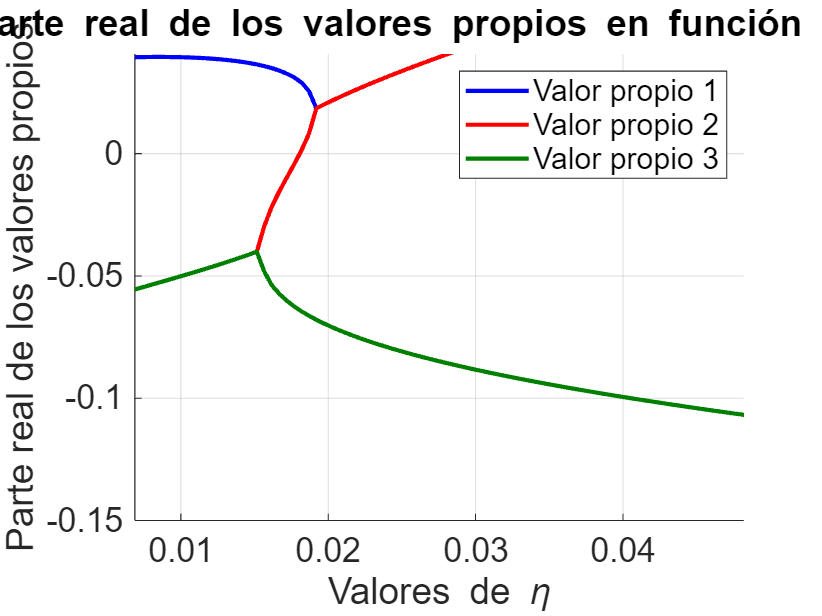

% Inicializar el rango de valores para eta
eta_values = linspace(0, 0.05, 100);
valores_propios_evaluados_num = zeros(length(eta_values), 3); % Matriz para almacenar valores propios

% Evaluar los valores propios para cada eta
for j = 1:length(eta_values)
    eta_actual = eta_values(j);
    
    % Evaluar los valores propios con el eta actual
    valores_propios_evaluados = subs(valores_propios_simplificados, eta, eta_actual);
    
    % Sustituir todos los parámetros simbólicos con sus valores numéricos
    valores_propios_evaluados_num(j, :) = double(subs(valores_propios_evaluados, param_vals, param_subs));
end

% Graficar solo la parte real de los valores propios
figure;
hold on;
plot(eta_values, real(valores_propios_evaluados_num(:, 1)), 'b-', 'DisplayName', 'Valor propio 1', 'LineWidth', 2);
plot(eta_values, real(valores_propios_evaluados_num(:, 2)), 'r-', 'DisplayName', 'Valor propio 2', 'LineWidth', 2);
plot(eta_values, real(valores_propios_evaluados_num(:, 3)), 'color', [0, 0.5, 0], 'DisplayName', 'Valor propio 3', 'LineWidth', 2);
xlabel('Valores de \eta');
ylabel('Parte real de los valores propios');
title('Parte real de los valores propios en función de \eta');
grid on;
legend show;

ax = gca;
ax.FontSize = 16;


hold off;

## Valores donde hay cambio de signo en valores pripios

% Detectar cambios de signo y guardar los intervalos
intervalos_eta = [];
for k = 1:length(eta_values)-1
    % Revisar si hay cambio de signo en cualquiera de los valores propios
    if (real(valores_propios_evaluados_num(k, 1)) * real(valores_propios_evaluados_num(k+1, 1)) < 0 ...
            || real(valores_propios_evaluados_num(k, 2)) * real(valores_propios_evaluados_num(k+1, 2)) < 0 ...
            || real(valores_propios_evaluados_num(k, 3)) * real(valores_propios_evaluados_num(k+1, 3)) < 0)
        
        % Guardar el intervalo donde ocurre el cambio de signo
        fprintf('Cambio de signo detectado entre eta = %.4f y eta = %.4f\n', eta_values(k), eta_values(k+1));
        intervalos_eta = [intervalos_eta; eta_values(k), eta_values(k+1)]; %#ok<AGROW>
    end
end

Cambio de signo detectado entre eta = 0.0177 y eta = 0.0182



% Mostrar los intervalos de cambio de signo identificados
disp('Intervalos donde se detectaron cambios de signo:');

Intervalos donde se detectaron cambios de signo:


disp(intervalos_eta);

    0.0177    0.0182




% Intentar resolver cada ecuación de valores propios == 0 dentro de los intervalos específicos
etas_criticos_encontrados = [];
for i = 1:size(intervalos_eta, 1)
    eta_start = intervalos_eta(i, 1);
    eta_end = intervalos_eta(i, 2);
    
    % Probar con varios puntos de inicio dentro del intervalo
    puntos_inicio = linspace(eta_start, eta_end, 5); % 5 puntos equiespaciados dentro del intervalo
    
    % Variable para almacenar soluciones dentro del intervalo
    etas_intervalo = [];
    
    for p = 1:length(puntos_inicio)
        % Usar cada punto como semilla inicial para vpasolve
        eta_midpoint = puntos_inicio(p);
        
        % Resolver cada valor propio dentro del intervalo
        eta_critico1 = vpasolve(valores_propios_simplificados(1) == 0, eta, eta_midpoint);
        eta_critico2 = vpasolve(valores_propios_simplificados(2) == 0, eta, eta_midpoint);
        eta_critico3 = vpasolve(valores_propios_simplificados(3) == 0, eta, eta_midpoint);
        
        % Concatenar los valores críticos encontrados en este subintervalo
        etas_criticos_intervalo = [eta_critico1; eta_critico2; eta_critico3];
        
        % Convertir los valores críticos a formato numérico
        etas_criticos_intervalo_numeric = double(etas_criticos_intervalo);
        
        % Filtrar solo valores finitos, reales y positivos de eta (considerando eta > 0)
        etas_filtrados = etas_criticos_intervalo_numeric(isfinite(etas_criticos_intervalo_numeric) & isreal(etas_criticos_intervalo_numeric) & (etas_criticos_intervalo_numeric > 0));
        
        % Agregar las soluciones de este subintervalo
        etas_intervalo = [etas_intervalo; etas_filtrados(:)]; %#ok<AGROW>
    end
    
    % Agregar los valores críticos únicos de este intervalo a la lista general
    etas_criticos_encontrados = [etas_criticos_encontrados; unique(etas_intervalo)]; %#ok<AGROW>
end

% Ordenar los valores críticos de eta encontrados
etas_criticos_reales_sorted = sort(etas_criticos_encontrados);

% Crear los intervalos asegurando que 0 esté al principio y inf al final
intervalos_filtrados = [0; etas_criticos_reales_sorted(:); inf]; % Asegúrate de que los valores sean columna

% Comprobar el resultado
disp('Intervalos filtrados:');
disp(intervalos_filtrados);

## REVISAR ESTABILDIAD

%% Revisar estabilidad en cada intervalo de eta
% Clasificar la estabilidad en cada intervalo
for i = 1:length(intervalos_filtrados)-1
    % Calcular el eta medio en cada intervalo
    eta_medio = (intervalos_filtrados(i) + intervalos_filtrados(i+1)) / 2;

    % Evaluar los valores propios con eta_medio
    valores_propios_evaluados = subs(valores_propios_simplificados, eta, eta_medio);

    % Sustituir todos los parámetros simbólicos con sus valores numéricos
    valores_propios_evaluados_num = double(subs(valores_propios_evaluados, param_vals, param_subs));

    % Verificar la estabilidad
    if all(real(valores_propios_evaluados_num) < 0)
        estabilidadd = 'Estable (Atractor)';
    elseif all(real(valores_propios_evaluados_num) > 0)
        estabilidadd = 'Inestable (Repulsor)';
    else
        estabilidadd = 'Punto de Silla';
    end

    % Mostrar el intervalo y su clasificación de estabilidad
    fprintf('Intervalo [%f, %f]: %s\n', intervalos_filtrados(i), intervalos_filtrados(i+1), estabilidadd);
end
